# **AER627 - Project 3 - Trajectory Generation**

## Kai Stewart - 501029849

clear;
clc;
close all;

%PHYSICAL PARAMS
L1 = 175; %mm
L2 = 145; %mm

%export selection
SHAPE = 'house';
OUTPUT_FILE = 'trajectory.csv';
N_INTERP = 20;

%For ref. A4 paper is 210 x 297mm 
% Format: [X, Y, PEN]  where 1 = PEN DOWN (drawing), 0 = PEN UP (moving)
square_waypoints = [0, 0, 0;
                    0 0, 1;
                    0, 100, 1;
                    100, 100, 1;
                    100, 0, 1;
                    00, 00, 1;
                    00, 00, 0];

sigma_waypoints = [160,  80, 0;
                   160, 80, 1;
                    60,  80, 1;   
                   110, 150, 1;   
                    60, 220, 1;   
                   160, 220, 1;
                   160, 220, 0];  

backwards_r_waypoints = [ 60,  80, 0;
                60, 80,  1;
                60, 220, 1;
                60, 220, 0;
                60, 80, 0;
                60, 80, 1;
               110,  80, 1;   
               130, 100, 1;   
               130, 130, 1;  
               110, 150, 1;   
                60, 150, 1;
               130, 220, 1;
               130, 220, 0];  

star_waypoints = [105,  70, 0;
                  105, 70, 1;
                  126, 118, 1;  
                  178, 118, 1;  
                  138, 152, 1;   
                  152, 205, 1;   
                  105, 172, 1;   
                   58, 205, 1;  
                   72, 152, 1;   
                   32, 118, 1;   
                   84, 118, 1;   
                  105,  70, 1;
                  105, 70, 0]; 

house_waypoints = [55, 220, 0;
                 55, 220, 1;
                 55, 130, 1;
                155, 130, 1;
                155, 220, 1;
                 55, 220, 1;
                 55, 220, 0;
                 55, 130, 0;
                 55, 130, 1;
                105,  70, 1;
                155, 130, 1;
                155, 130, 0;
                 90, 220, 0;
                 90, 175, 1;
                120, 175, 1;
                120, 220, 1;
                120, 220, 0;
                 65, 165, 0;
                 65, 165, 1;
                 65, 145, 1;
                 85, 145, 1;
                 85, 165, 1;
                 65, 165, 1;
                 65, 165, 0];

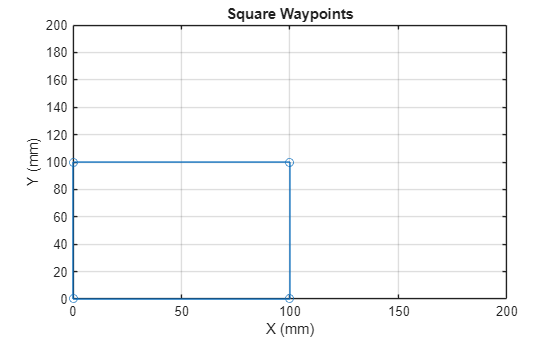

%WORKSPACE

%%plotting
%below is just for reference of the waypoints, it includes traversals where the pen is up
figure(1); 
square_waypoints_x = square_waypoints(:,1);
square_waypoints_y = square_waypoints(:,2);
plot(square_waypoints_x, square_waypoints_y, '-o')
grid on
xlabel('X (mm)')
ylabel('Y (mm)')
xlim([0 200]);
ylim([0 200]);
title('Square Waypoints')

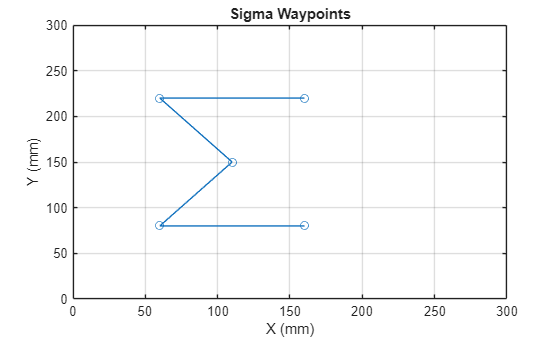


figure(2); 
sigma_waypoints_x = sigma_waypoints(:,1);
sigma_waypoints_y = sigma_waypoints(:,2);
plot(sigma_waypoints_x, sigma_waypoints_y, '-o')
grid on
xlabel('X (mm)')
ylabel('Y (mm)')
xlim([0 300]);
ylim([0 300]);
title('Sigma Waypoints')

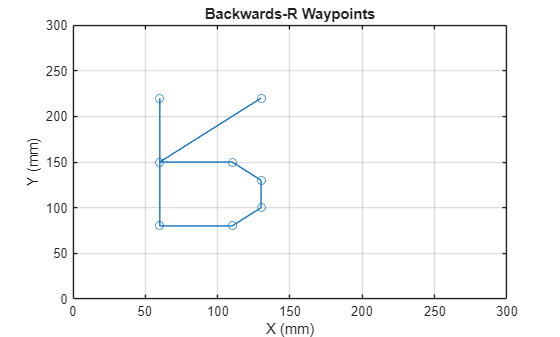


figure(3); 
backwards_r_waypoints_x = backwards_r_waypoints(:,1);
backwards_r_waypoints_y = backwards_r_waypoints(:,2);
plot(backwards_r_waypoints_x, backwards_r_waypoints_y, '-o')
grid on
xlabel('X (mm)')
ylabel('Y (mm)')
xlim([0 300]);
ylim([0 300]);
title('Backwards-R Waypoints')

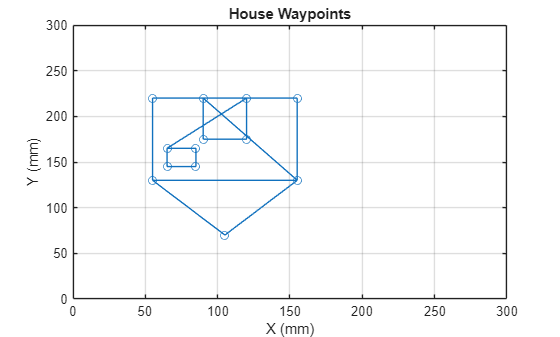


figure(4); 
house_waypoints_x = house_waypoints(:,1);
house_waypoints_y = house_waypoints(:,2);
plot(house_waypoints_x, house_waypoints_y, '-o')
grid on
xlabel('X (mm)')
ylabel('Y (mm)')
xlim([0 300]);
ylim([0 300]);
title('House Waypoints')

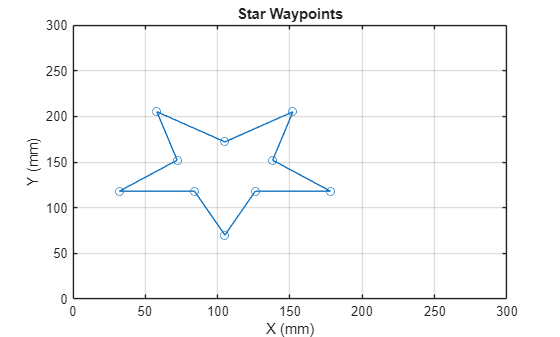


figure(5); 
star_waypoints_x = star_waypoints(:,1);
star_waypoints_y = star_waypoints(:,2);
plot(star_waypoints_x, star_waypoints_y, '-o')
grid on
xlabel('X (mm)')
ylabel('Y (mm)')
xlim([0 300]);
ylim([0 300]);
title('Star Waypoints')

**SWITCH CASE FOR DATA SET**

%switch case for what shape are we exporting?
switch lower(SHAPE)
    case 'square'
        waypoints = square_waypoints;
    case 'sigma'
        waypoints = sigma_waypoints;
    case 'backwards_r'
        waypoints = backwards_r_waypoints;
    case 'house'
        waypoints = house_waypoints;
    case 'star'
        waypoints = star_waypoints;
end


**INTERPOLATION**

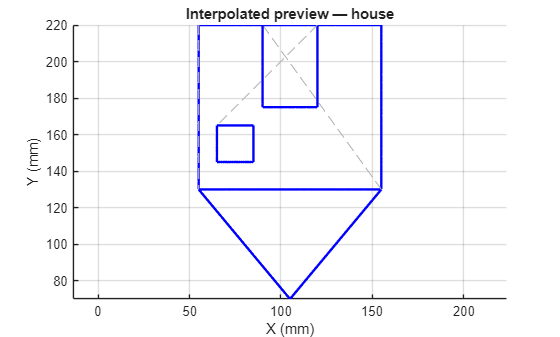

%interpolation between waypoints
interp_pts = []; 
 
for i = 1:size(waypoints,1)-1
    x0  = waypoints(i,   1);  y0  = waypoints(i,   2);
    x1  = waypoints(i+1, 1);  y1  = waypoints(i+1, 2);
    pen = waypoints(i+1, 3);  
 
    if pen == 1 %if the segment is a draw segment
        t_vals = linspace(0, 1, N_INTERP + 1); %interpolate 
        for t = t_vals(2:end)   % skip first to avoid duplicate points
            xi = x0 + t * (x1 - x0);
            yi = y0 + t * (y1 - y0);
            interp_pts(end+1, :) = [xi, yi, 1];
        end
    else
        % do not interpolate for pen up traversal segments 
        interp_pts(end+1, :) = [x1, y1, 0];
    end
end
 
% connect the first waypoint to the rest of the interpolated trajectory  
interp_pts = [waypoints(1,:); interp_pts];

%interpolation visualization 
figure(6); 
hold on; 
axis equal;
grid on;
title(sprintf('Interpolated preview — %s', SHAPE));
xlabel('X (mm)'); 
ylabel('Y (mm)');

for i = 2:size(interp_pts,1)
    x1p = interp_pts(i-1,1); y1p = interp_pts(i-1,2);
    x2p = interp_pts(i,  1); y2p = interp_pts(i,  2);
    if interp_pts(i,3) == 1
        plot([x1p x2p],[y1p y2p],'b-','LineWidth',1.8);
    else
        plot([x1p x2p],[y1p y2p],'--','Color',[0.7 0.7 0.7],'LineWidth',0.8);
    end
end

**FORMAT FOR OUTPUT**

n = size(interp_pts, 1);
output = zeros(n, 3);   % [J1_deg, J2_deg, pen]
J1_prev = 0;
J2_prev = 0;
skipped = 0;
 
for i = 1:n
    x = interp_pts(i, 1);
    y  = interp_pts(i, 2);
    pen_state = interp_pts(i, 3);
 
    r = sqrt(x^2 + y^2);
    rmax = L1 + L2;
    rmin = abs(L1 - L2);
 
    if r > rmax || r < rmin
        warning('Point %d [%.1f, %.1f]mm out of reach (r=%.1fmm, need %.1f-%.1fmm). ',i, x, y, r, rmin, rmax);
        output(i,:) = [J1_prev, J2_prev, pen_state];
        skipped = skipped + 1;
        continue
    end
 
    [J1, J2] = ik_min_motion(x, y, L1, L2, J1_prev, J2_prev);
    output(i,:) = [J1, J2, pen_state];
    J1_prev = J1;
    J2_prev = J2;
end
 
fprintf('%d points total, %d skipped and out of reach\n', n, skipped);

328 points total, 0 skipped and out of reach


 
% figure(7);
% subplot(2,1,1); stairs(1:n, output(:,1), 'b'); grid on;
% ylabel('J1 (deg)'); title(sprintf('Joint angles — %s', SHAPE));
% subplot(2,1,2); stairs(1:n, output(:,2), 'r'); grid on;
% ylabel('J2 (deg)'); xlabel('Trajectory point index');
 

**FILE OUTPUT**

fid = fopen(OUTPUT_FILE, 'w');
for i = 1:n
    fprintf(fid, '%.4f,%.4f,%d\n', output(i,1), output(i,2), int32(output(i,3)));
end
fclose(fid);
fprintf('Wrote %d rows to %s\n', n, OUTPUT_FILE);

Wrote 328 rows to trajectory.csv


**FUNCTION STORAGE **

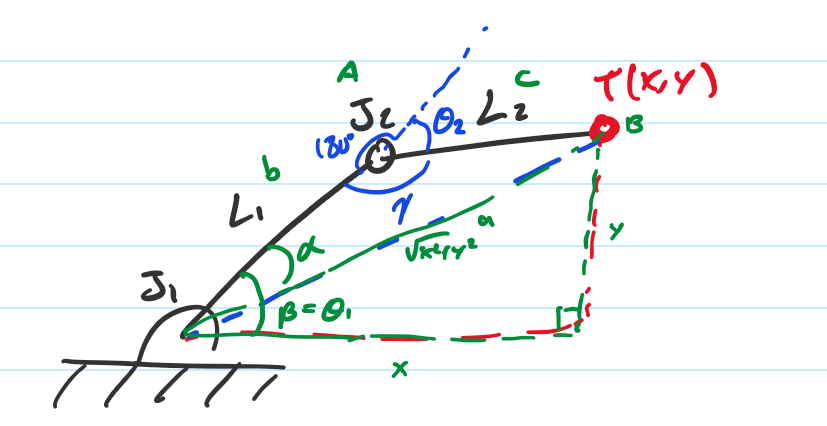

%calculates inv kinematics of 
function [J1, J2] = inverse_kinematics(x, y, L1, L2, elbow_up)
    cos_gam = (x^2 + y^2 - L1^2 - L2^2) / (-2 * L1 * L2);
    gam = acosd(max(-1, min(1, cos_gam))); %we clamp because weird floating point stuff was happening 
    J2 = (180 - gam) * (2*double(elbow_up) - 1); %double is here to convert boolean flag (str) into an (int)
 
    beta = atan2d(y, x);
    r = sqrt(x^2 + y^2);
    cos_alfa = (L2^2 - L1^2 - x^2 - y^2) / (-2 * L1 * r);
    alfa = acosd(max(-1, min(1, cos_alfa)));
    J1 = beta + alfa * (2*double(elbow_up) - 1);
end

%evaluates both elbow configs and pick the one with less total joint travel
%and also prevents mid-trajectory configuration flips
function [J1, J2] = ik_min_motion(x, y, L1, L2, J1_prev, J2_prev)
    [J1u, J2u] = inverse_kinematics(x, y, L1, L2, true);
    [J1d, J2d] = inverse_kinematics(x, y, L1, L2, false);
    if (abs(J1u-J1_prev) + abs(J2u-J2_prev)) <= (abs(J1d-J1_prev) + abs(J2d-J2_prev))
        J1 = J1u; J2 = J2u;
    else
        J1 = J1d; J2 = J2d;
    end
end



**The Dump**

%define a 2-link IK function that outputs 2 joint angles based on a waypoint (x,y) and the physical params
% function [J1, J2] = inverse_kinematics(x, y, L1, L2) 
%     J2 = acos((x^2 + y^2 - L1^2 - L2^2) / (2 * L1 * L2)); %derived from law of cosines find J2 using a target and distances assuming arm is perfectly straight. 
%     J1 = atan2(y, x - atan2(L2*sin(J2), L1 + L2*cos(J2))); % then find J1 by calculating the J1 angle to target and subtracting J 
% end

%IK, outputs J1 and J2 angles and takes in target points (x,y) and the lengths of the arms 
% function [J1, J2] = inverse_kinematics(x, y, L1, L2)
%     gam = acosd((x^2 + y^2 -L1^2 - L2^2)/(-2*L1*L2));
%     J2 = (180 - gam);
%     beta = atan2d(y, x);
%     alfa = acosd((L2^2 - L1^2 -x^2 -y^2)/(-2*L1*sqrt(x^2 + y^2)));    
% 
%     if(J2 > 0)
%         J1 = beta + alfa;
% 
%     else if (J2 < 0)
%         J1 = beta - alfa;
% 
%     else
%         J1 = alfa;
% 
%     end  
% end

% %export instructions out to SD
% function export_to_sd(joint_angles, filename)
% 
%     %outputs to
%     T = array2table(joint_angles, 'VariableNames', {'j1_deg', 'j2_deg'});
%     writetable(T, filename);
%     fprintf('Successfully exported %d trajectory points to %s\n', size(joint_angles,1), filename);
% end

% % generate interpolated trajectory
% function joint_angles = generate_trajectory(waypoints, n_interp, l1, l2)
%     joint_angles = [];
%     for i = 1:size(waypoints, 1) - 1
%         x0 = waypoints(i, 1);   y0 = waypoints(i, 2);
%         x1 = waypoints(i+1, 1); y1 = waypoints(i+1, 2);
%         for t = linspace(0, 1, n_interp)
%             x = x0 + t*(x1 - x0);
%             y = y0 + t*(y1 - y0);
%             [q1, q2] = inverse_kinematics(x, y, l1, l2);
%             joint_angles = [joint_angles; rad2deg(q1), rad2deg(q2)];
%         end
%     end
% end